# **IO3xx Serial Loopback Interrupt**

This example shows how to perform a loopback test using IO3xx Serial with the Serial Interrupt. You can test the basic IO3xx serial functionality by running this example.

## Setup

### Prerequisites

You will require the following to run this example:

- A Speedgoat real-time target machine with one I/O module from the IO3xx family installed

- A Speedgoat configuration file that supports **3x serial channels**

- A connector cable from the I/O module to the terminal board

- A terminal board with jumper wires

### Test Setup

This example is a loopback on the serial channels 1–3. The Tx pin of each channel must be connected to the Rx pin of the same channel. You must therefore connect the pins on the terminal board where these channels are located. The exact pins depend on the configuration file used.

In the pin mapping of your configuration file, locate the functionalities specified in the table below and then locate the corresponding pins on the terminal board. Connect these pins with jumper wires. 

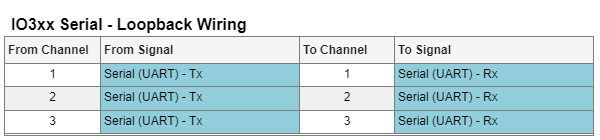

## Initialize and Open the Simulink model

 
% Open Simulink model
modelName = 'sgMdl_IO3xx_Serial_Loopback_Interrupt';
open_system(modelName);

Before the Simulink model can be built, the I/O module and configuration file must be specified in the IO3xx Setup block, as this example can be executed on different configurable I/O modules. First, open the mask of the IO3xx Setup block and select your I/O module from the drop-down. Once the mask has extended, select the configuration file that supports the required functionalities.

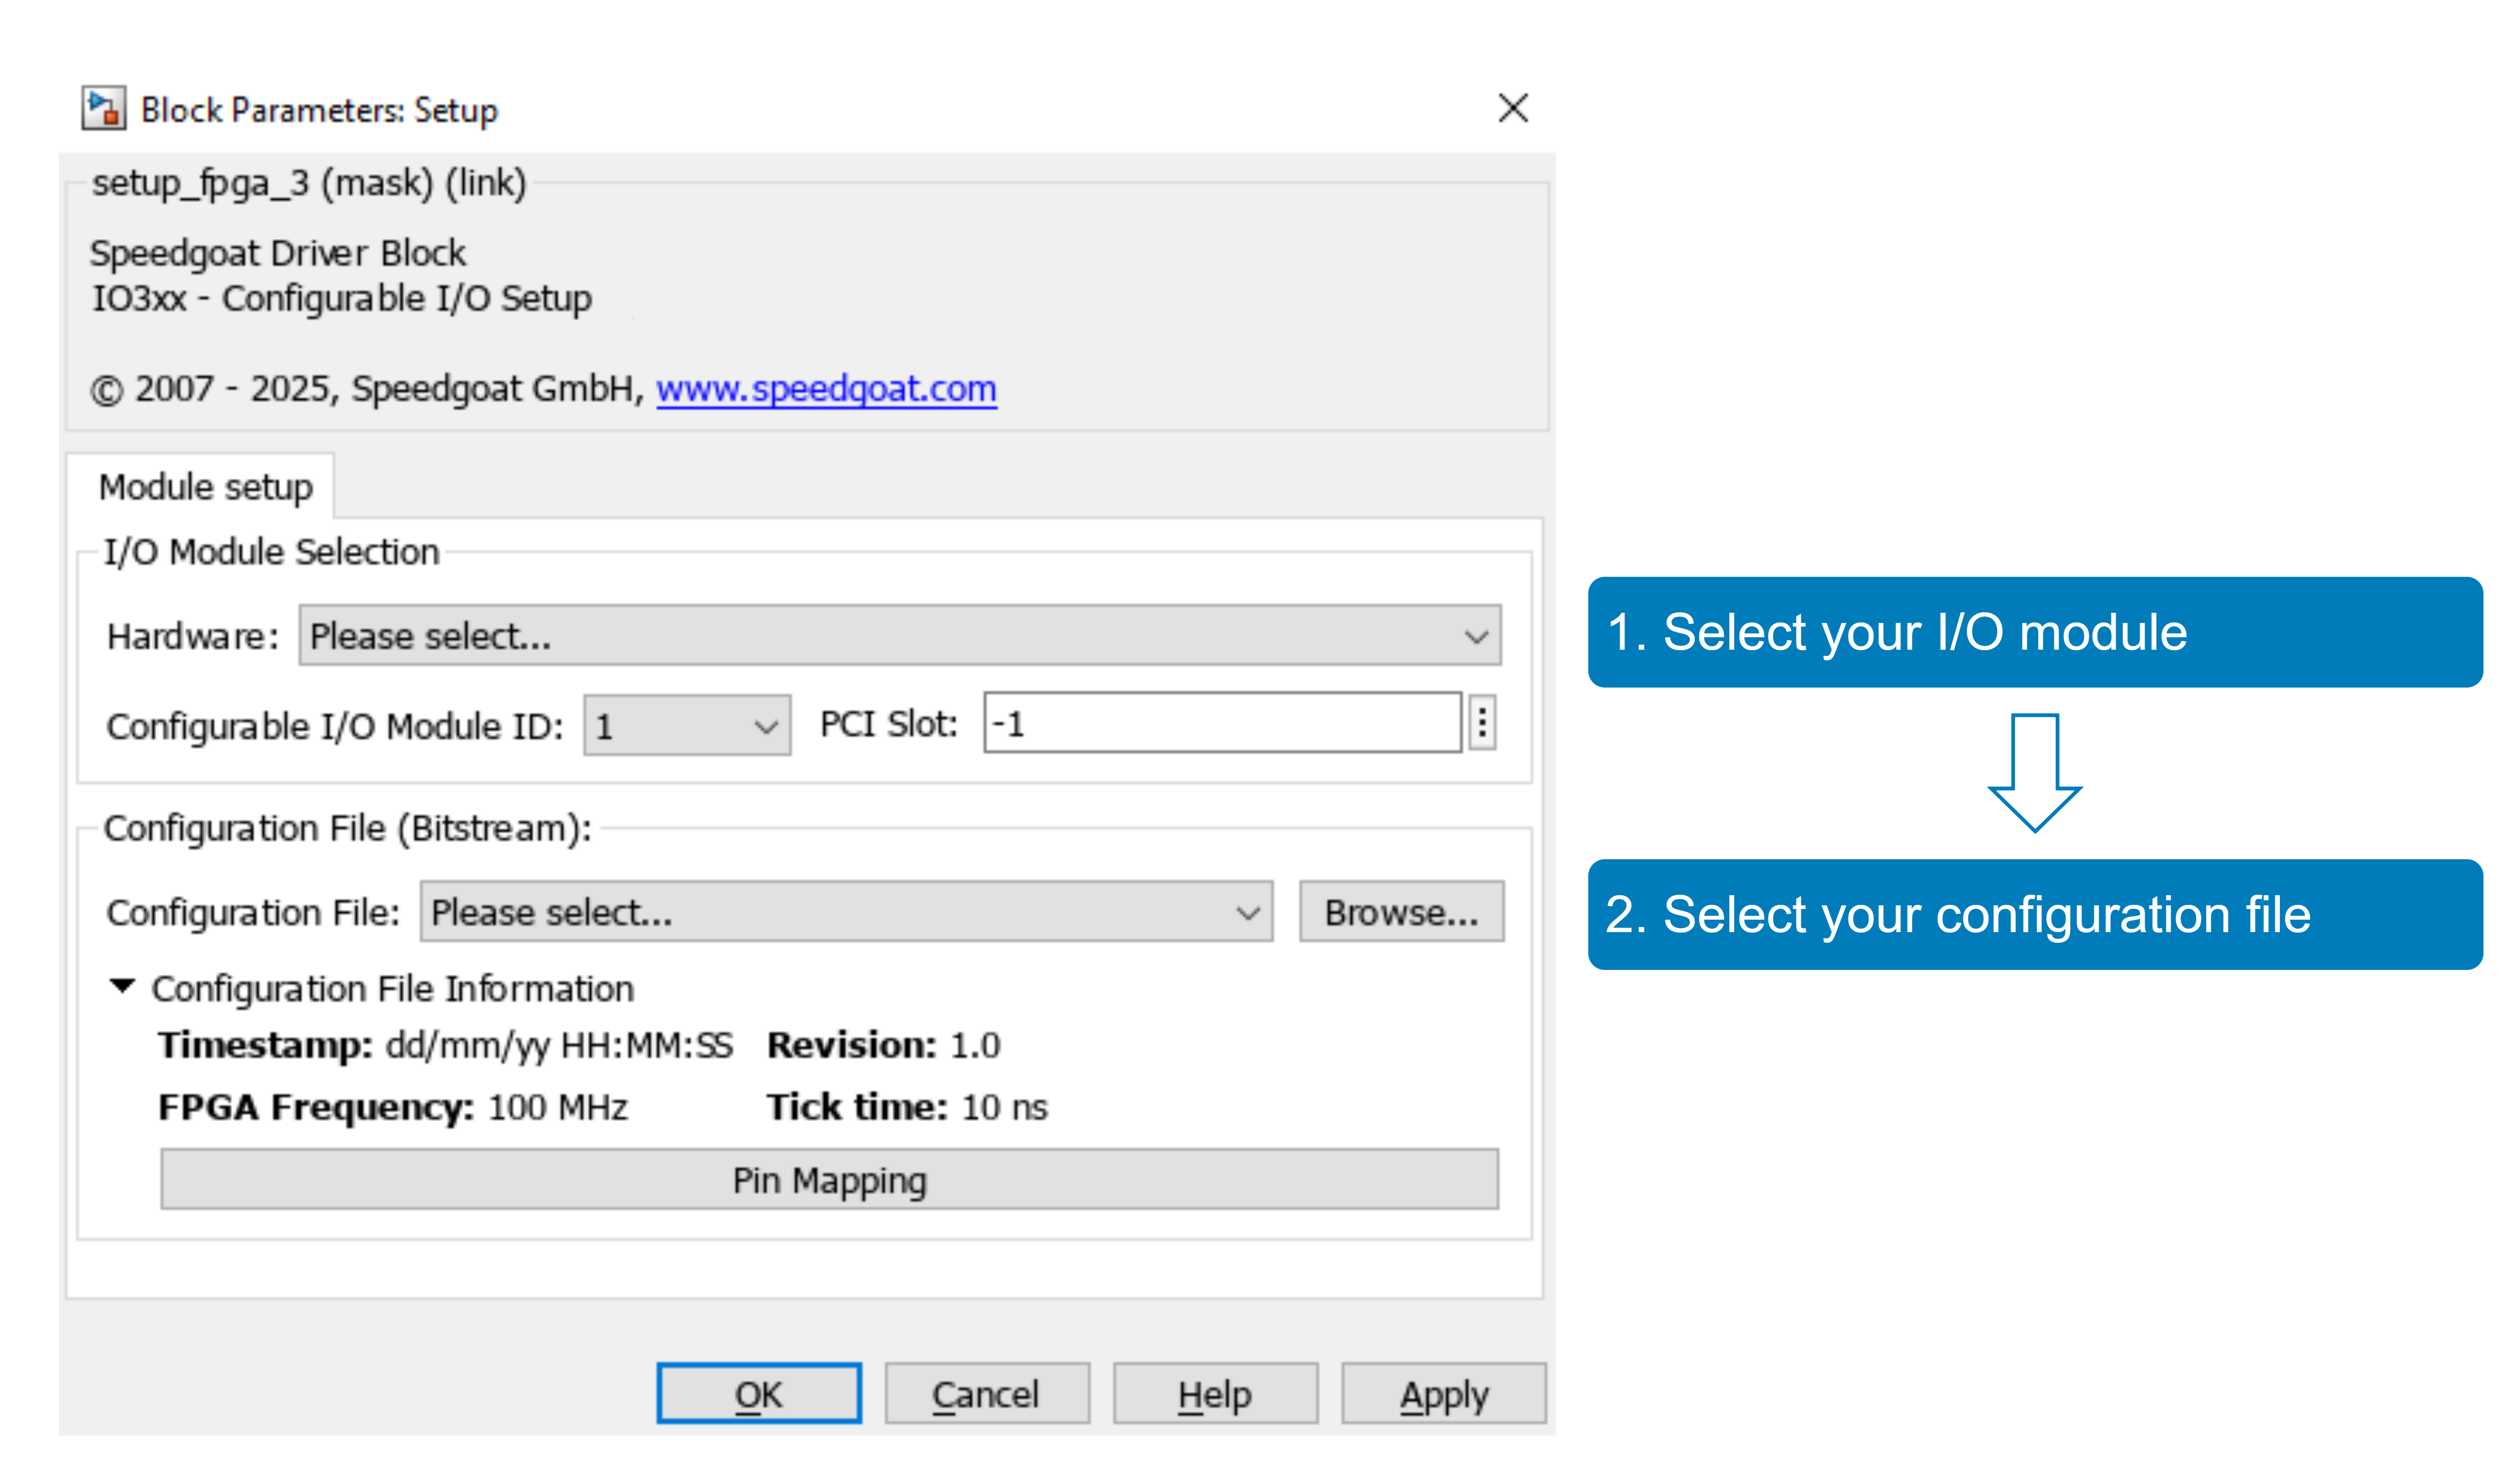

With the **Pin Mapping** button you can now check where the functionalities are located.

After you set your I/O module and the configuration file, you also need to select the correct Serial Interrupt source. To do so, double-click the **Serial Interrupt** Setup block and select the corresponding "IO3xx Serial Interrupt" from the list:

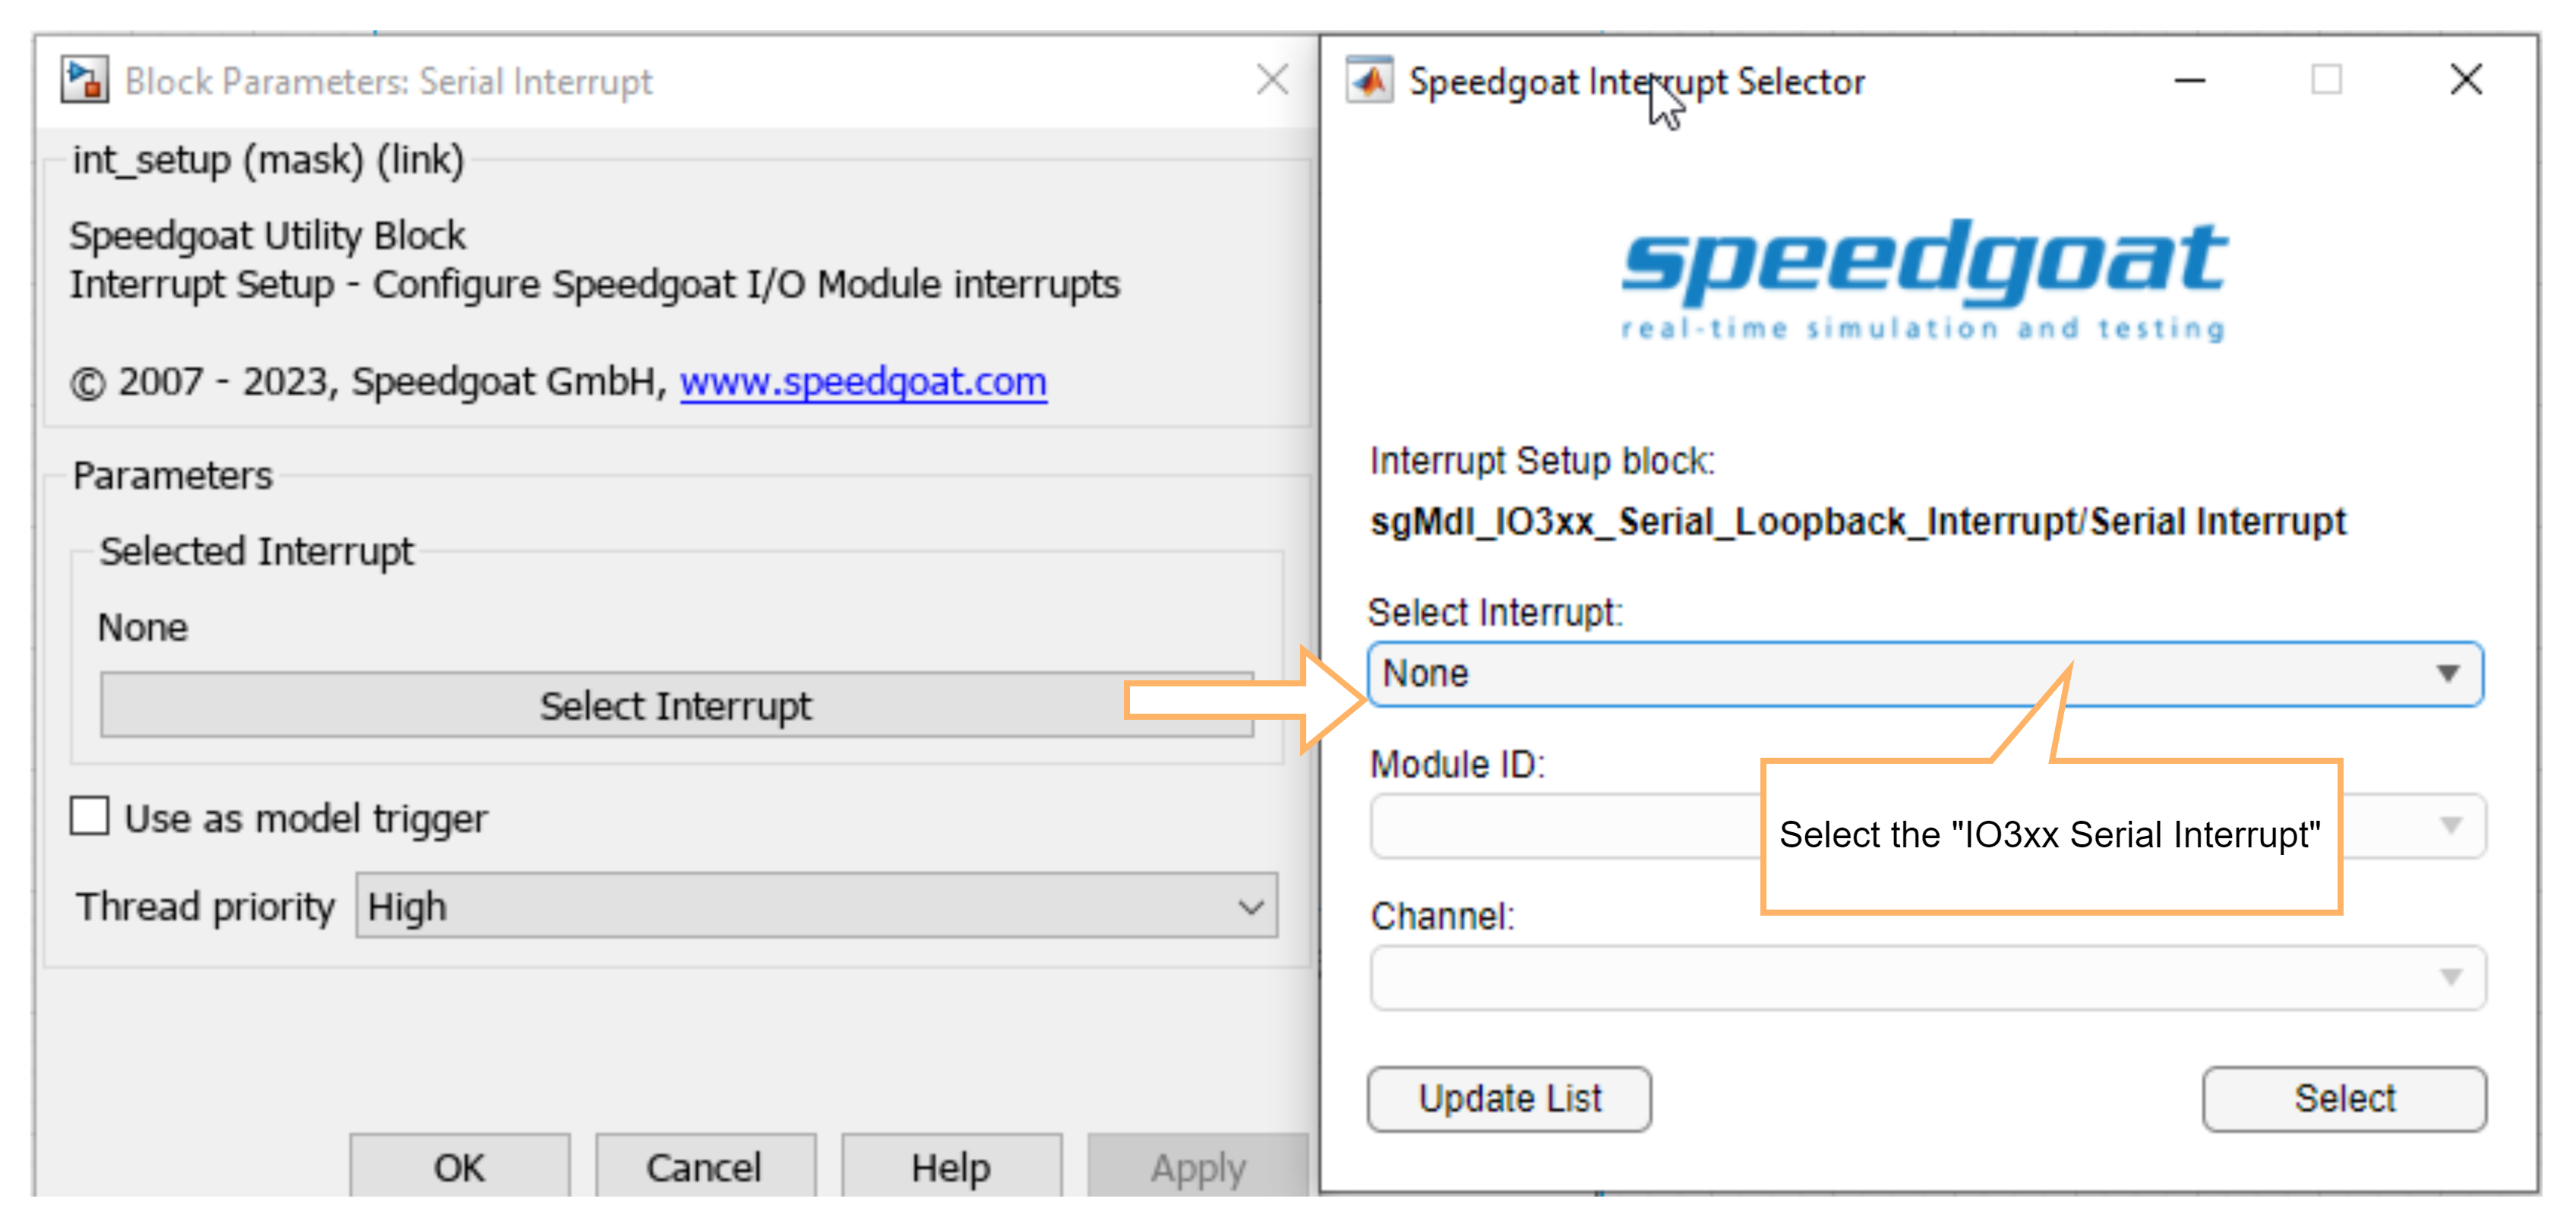

### Model Description

#### Using the serial interrupt

In this model, serial channels 1 to 3 transmit a vector of data and then serial channels 1 to 3 receive it. Reading the received values uses the Serial Interrupt feature. The approach of using the Serial Interrupt is useful when only the IO3xx Serial Receiver is used to receive serial data from an external device. In this situation, reading the serial received data with a fixed simulation time leads to unsynchronized data reception because the external device that is transmitting data cannot be synchronized to this model step:

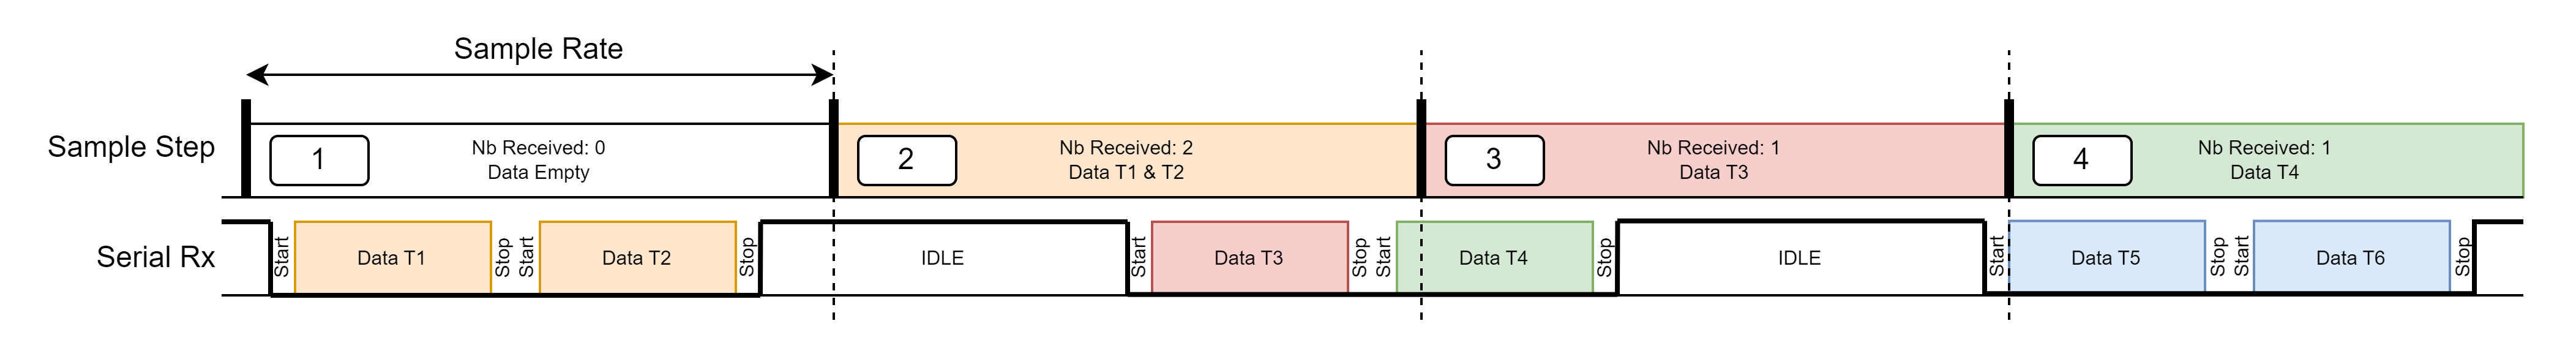

In this example, data T1 and T2 have been received and are available in sample step 2. In sample step 3 however, only data T3 has been received, while data T4 was not received before start of step 3 and therefore is not available before sample step 4.

The following image shows the timing behavior in case the serial interrupt is used:

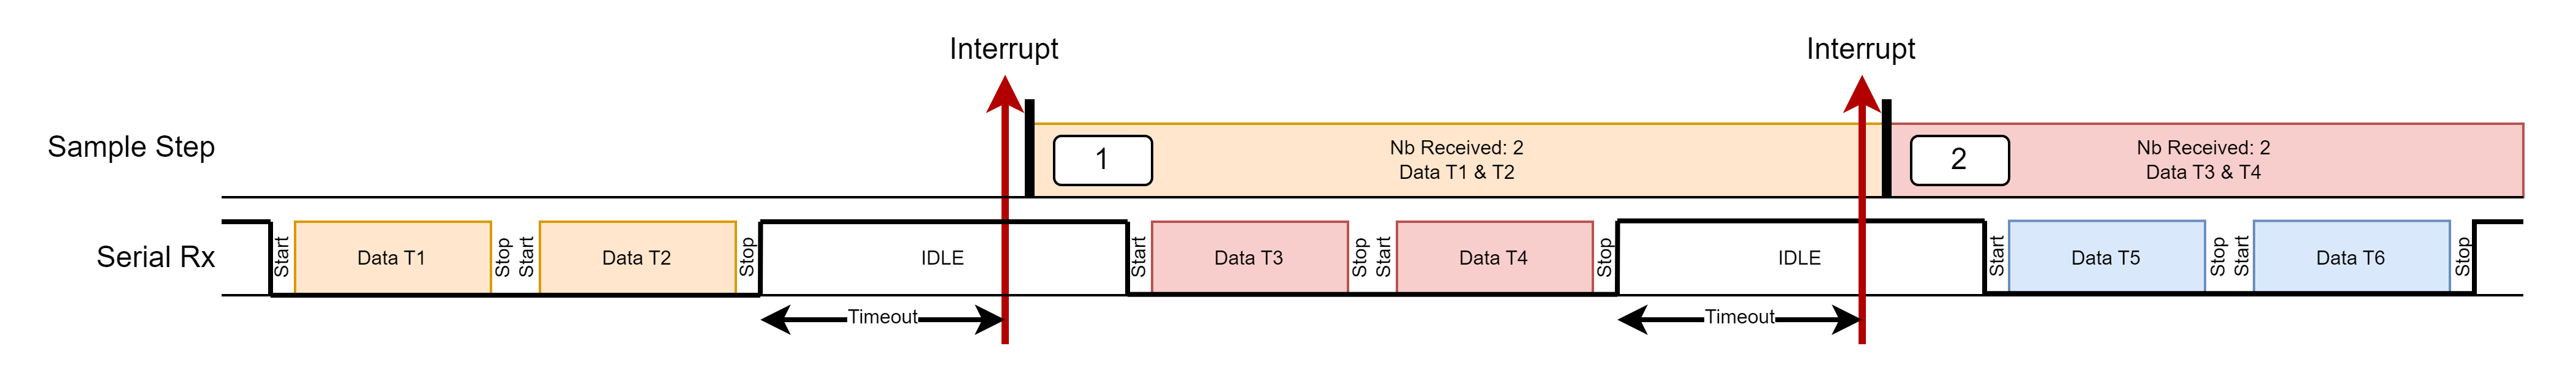

The serial interrupt is triggered after a settable timeout. This interrupt can be used to trigger a subsystem where the serial data can be consistently read out. Note that after the interrupt trigger, the reading of the previously received data takes some amount of time. It must be ensured that the following serial data (T3 in this image) is not finished before this amount of time to read the previous serial data has elapsed. Therefore, in case the external device sends a high amount of serial data within one stream (before the timeout happens), you must nevertheless ensure that the data repetition time of your external device is not too high.

#### Model Details

In the area **Serial message assemble and transmit**, the serial Tx data are set up that are looped back to the serial Rx receivers so we can check the data.

The block **Serial Setup** defines the setup of the Serial transmitters and receivers. The tab **Module Setup** defines serial channels 1 to 3 to be used. 1 MBaud transfer rate is set for all channels on the tab **Bitrate**. The tab **UART frame** sets up details of the protocol. In the tab **Timeout setup** we can define the above described timeout to trigger a serial interrupt. The timeout setting is defined in number of UART words. In this example, the baudrate is set to 1 MHz and the frame is defined as 8 data-bits and 2 stop-bits, 1 start-bit is always used. This means if we set the timeout to 1, an interrupt will be generated after 1/1 MHz * 11 bits = 11 µs there was no activity on the serial Rx. Note that when using several channels, it must be ensured that the interrupts are not triggered timely too close to each other as this might lead to a CPU overrun. Therefore, the timeout for the 3 used channels is set to [1 5 9].

The block **Serial Interrupt** selects the Serial Interrupt source and generates an output port, which then can be used to trigger the subsystem **Serial Read**.

The subsystem **Serial Read** contains the needed blocks to read out the serial data of all 3 used channels; The block **Read Timeout Status** is mandatory to reset the pending serial Rx interrupts on one side; on the other side, this block contains an output that indicates which of the serial Rx channels triggered an interrupt. In this example, we are using the serial Rx channels 1 to 3. In case the serial Rx channel 1 triggered the interrupt, the element 1 in the output **Status** will be high. Therefore, we demux the Status output in the 3 used channels and connect them to an enabled subsystem **Serial Rx Read 1 to 3**. These subsystems finally contain the **Serial Read HW FIFO**, which are used to read out the Rx data of the serial Rx FIFO.

## Build, Download, and Run the Example

To run the example, either run the following code section or click the **Run on Target** button in the **REAL-TIME** tab in the Simulink model:

 
% Build the Simulink model
slbuild(modelName);         % this will create the real-time application file (.mldatx)

% Create and connect to the Speedgoat real-time target machine
tg = slrealtime;            
tg.connect;

% Download and install the real-time application on the target machine
tg.load(modelName); 
tg.setStopTime(10);

% Connect the Simulink model with external mode to the real-time application on the target machine
set_param(modelName,'SimulationMode','external')    % put model into External Mode
set_param(modelName,'SimulationCommand','connect')  % connect with External Mode  

% Start the real-time application
tg.start;

% Wait a few seconds and then stop the real-time application on the target machine
pause(10)
tg.stop;

### Check the Results

To check the loopback is working as expected, open the Simulink scope that is connected to the Serial Read block. The scope must display the serial data:

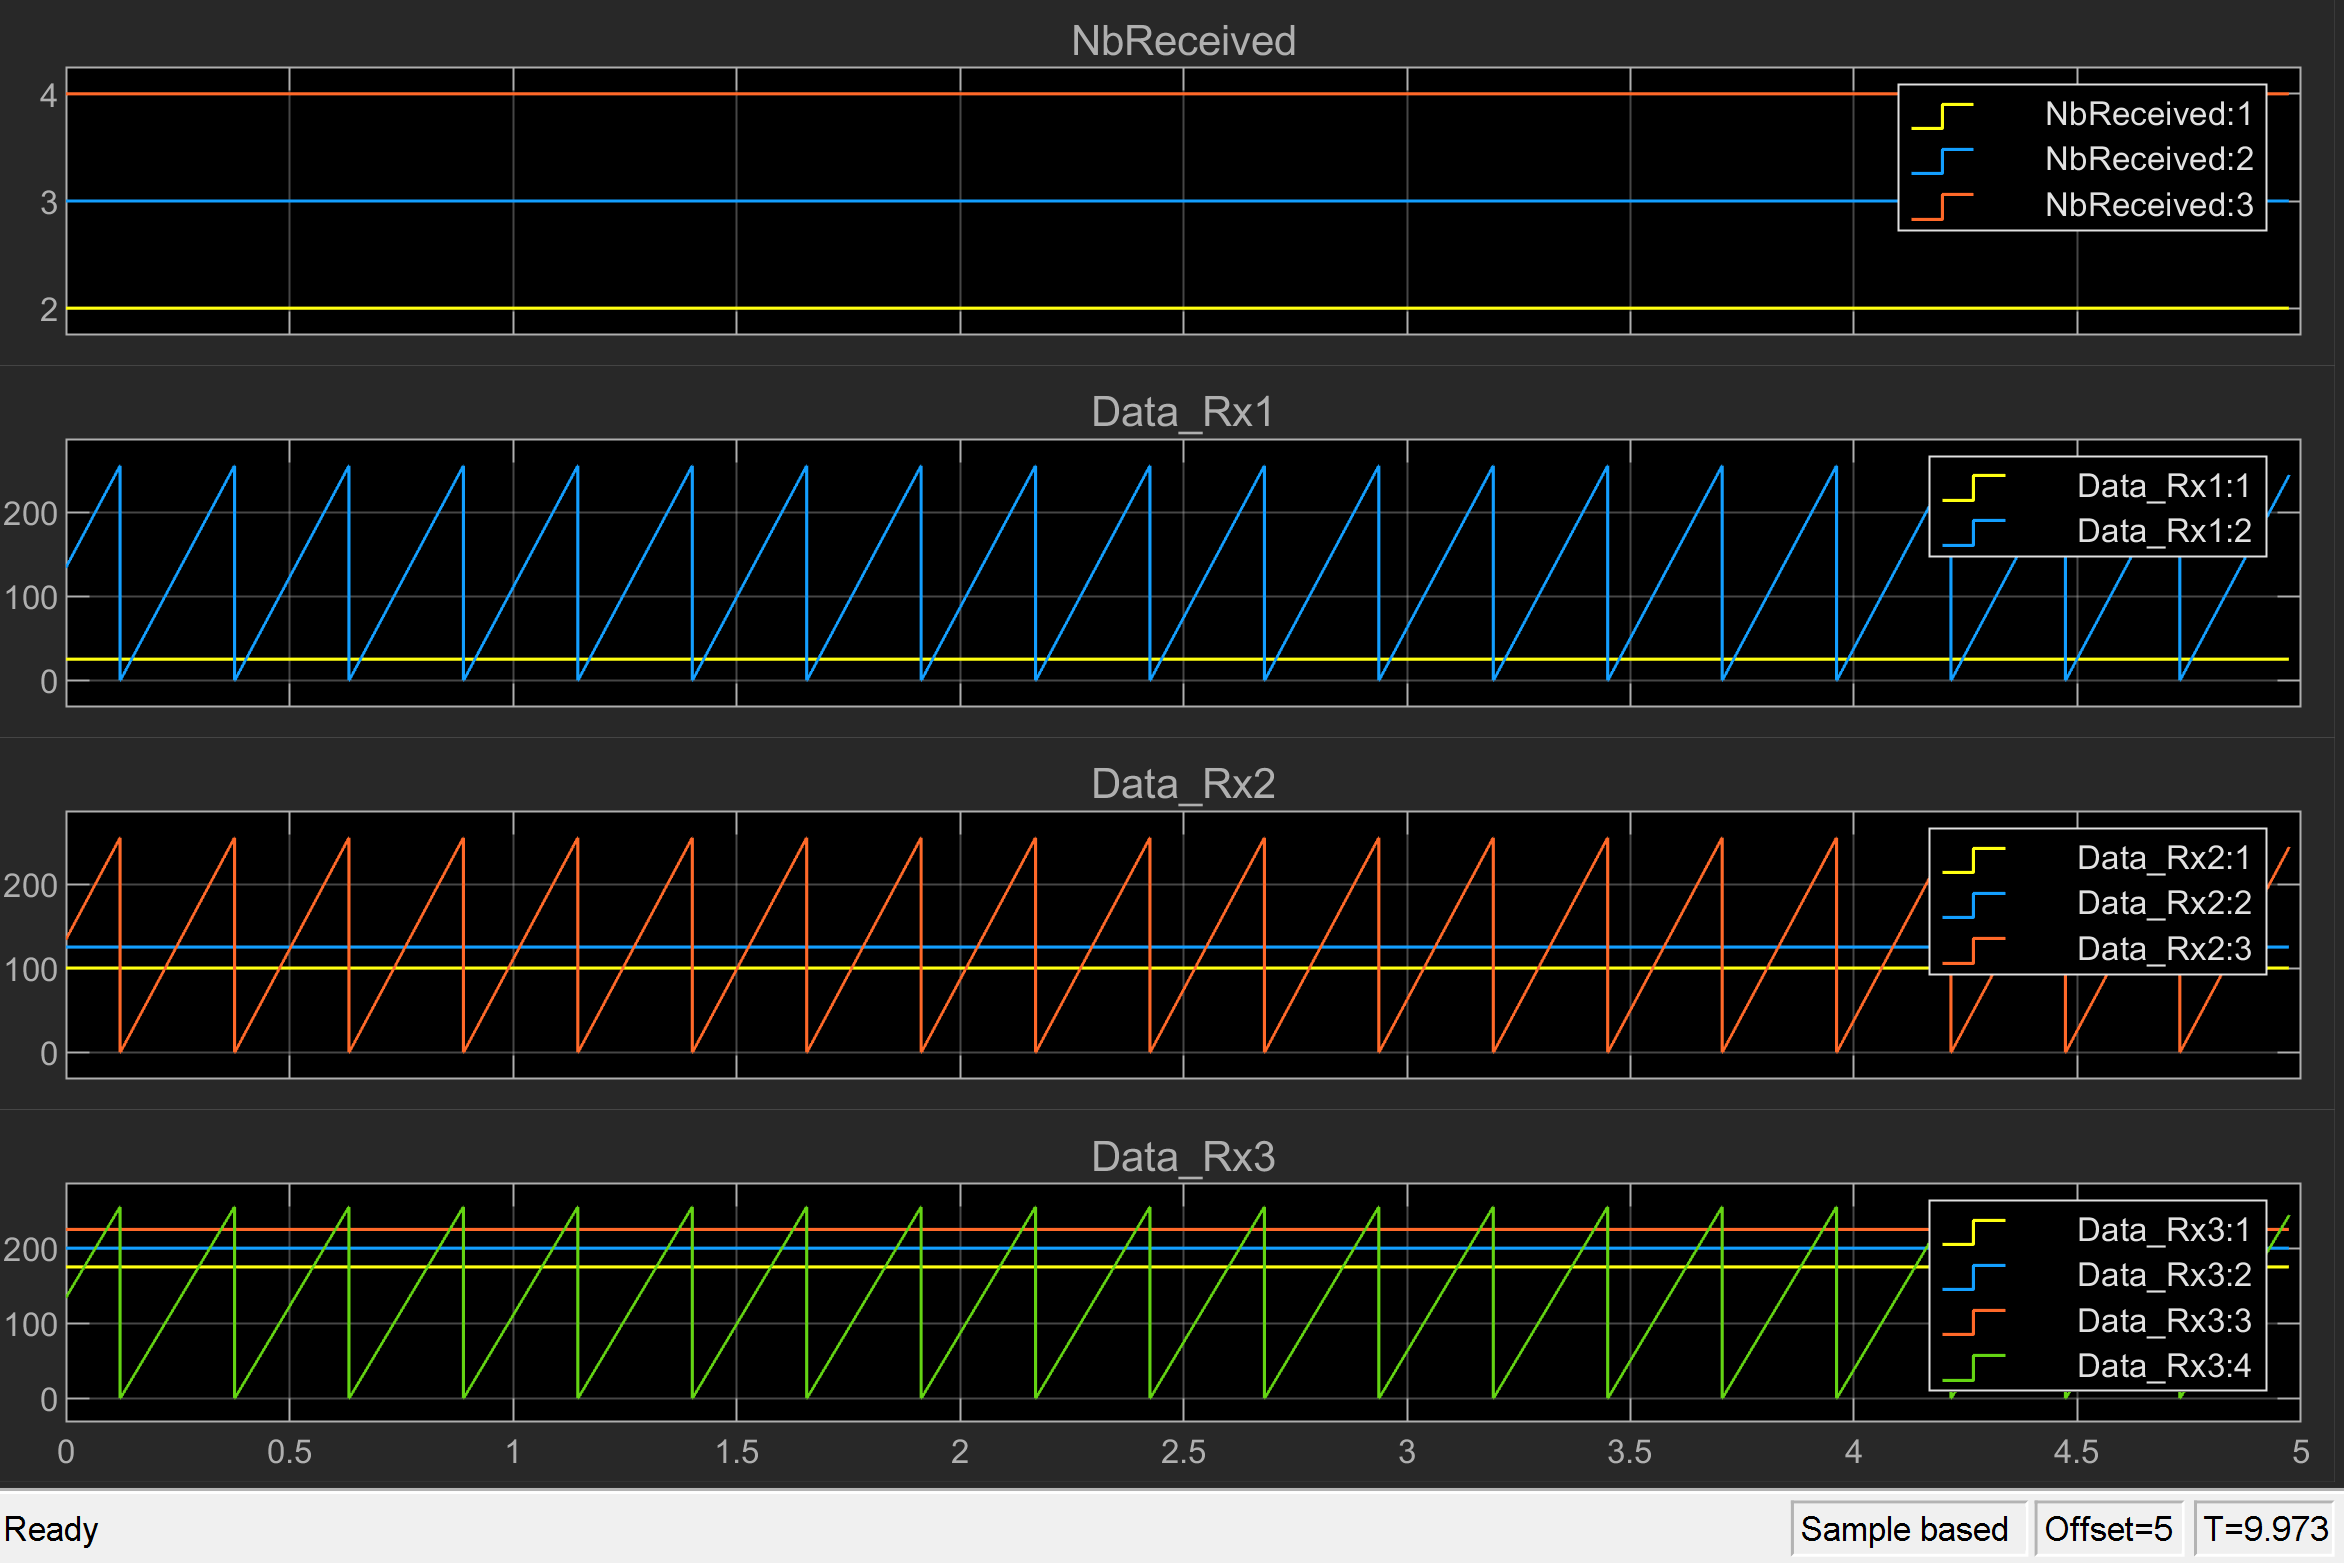

The part **NbReceived** displays the number of received bytes. The following values are expected:

- Channel1: 2 Rx Data

- Channel2: 3 Rx Data

- Channel3: 4 Rx Data

The part **Data_Rx1** displays the received data of the serial Rx channel1:

- Data1: fixed to decimal 25

- Data2: free running counter

The part **Data_Rx2** displays the received data of the serial Rx channel2:

- Data1: fixed to decimal 100

- Data2: fixed to decimal 125

- Data3: free running counter

The part **Data_Rx3** displays the received data of the serial Rx channel3:

- Data1: fixed to decimal 175

- Data2: fixed to decimal 200

- Data3: fixed to decimal 225

- Data4: free running counter

## Additional References

- [IO3xx Serial Documentation and Examples](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_serial)